%SM: choose sightseeing here
%SM: create an array with strings of cities
cityStrings = ["Berlin", "Paris", "Rome", "Tokyo", "TestSet"];

%SM: choose a city
city = cityStrings(1)

city = "Berlin"


%SM: check a parameter
popularity = false;
price = false;
visiting_time = false;

%SM: in the future: use it like "if(popularity) doStuff()"
%ST: Get the function, corresponding to chosen metric -> refactor function

%ST: This will call the dataSet function and return the chosen dataset
destSights = getCityDataSet(city);
%ST: Using our own eta instead of euclidean distance
eta = getCityEta(city);

%figure(1);
%text([destSights(:).lat],[destSights(:).long],[destSights(:).name])
%hold on;
%plot([destSights(:).lat],[destSights(:).long],'bo-')


% ST:                           Algorithm Edit Comments
% For variable and param explanation please visit TSP_ACO
%    SETTING PARAMS     %
% exploit vs explore

%q_0 = .1;
%numAnts = 25;
%beta = .030;
%maxIts = 1000;
%Q = 100;
%rho = .5;

%q_0 = .23; % approx. best at 0.23;
%numAnts = 29; % approx. best at 29;
%beta = 0.02; %approx. best at 0.02;
%maxIts = 710; %approx. best at 710;
%Q = 49; %approx. best at 49;
%rho = 0.36; %approx. best at 0.36;

q_0 = 0.12; % approx. new best at 0.12;
numAnts = 26; % approx. new best at 26;
beta = 0.02; %approx. new best at 0.01; WHY IS THAT??????????
maxIts = 950; %approx. new best at 950;
Q = 14; %approx. new best at 14
rho = 0.22; %approx. new best at 0.22

params = struct('q_0', q_0, 'numAnts', numAnts, 'beta', beta, 'Q', Q, 'rho', rho);

fprintf('Running ' + city + ' Sightseeing Optimization on  %i Sights with the following parameters:\n', length(destSights));

Running Berlin Sightseeing Optimization on  11 Sights with the following parameters:


disp(params);

        q_0: 0.1200
    numAnts: 26
       beta: 0.0200
          Q: 14
        rho: 0.2200




% Tau will be populated dynamically, blank for now
tau = ones(length(destSights),length(destSights));

% Creates an ititial path
bestPath = 1:length(destSights);
bestScore = newScorePath(0, bestPath, destSights, eta);
fprintf('Initial Score: %f', bestScore);

Initial Score: 144.000000

numIts = 1;
scores = zeros(1, maxIts);

while numIts < maxIts;
	% for ant_k in colony
	for ant_k = 1:numAnts
		
		% Init empty path and place ant_k at a random starting index
		path = zeros(1, length(destSights));
		currInd = 1;
		path(currInd) = randi(length(destSights));
		
		% Need to track of where we have not been
		unvisited = 1:length(destSights);
		unvisited(path(1)) = [];
		
		
		% While ant has not visited all cities
		for currInd = 1:(length(destSights) - 1)
			r = path(currInd);
			
			% Here we find the destination city s
			if (rand < q_0)
				[~, sInd] = max(tau(r, unvisited) .* eta(r, unvisited).^beta);
				s = unvisited(sInd);
			else
				vec = tau(r, unvisited) .* (eta(r, unvisited).^beta);
				probs = vec ./ sum(vec);
				
				% Sometimes prob vec is a zero vector, giving nans. In
				% this case they are all equally bad so we choose 1st
				if any(isnan(probs))
					sInd = 1;
				else
					
					% Draws the city to visit based on the above probabilities:
					%    The ways this works is that the ith element of probs
					%    defines the probability of selecting ith element of
					%    unvisited array. Thus if we want to draw an element
					%    based on this distribution, we treat the probabilities
					%    as a partitioning of the unit interval. We then choose
					%    a partition by generating a random number and then
					%    selecting the interval in which the number lies. By
					%    taking the cumulative sum of the probabilities, we get
					%    the partitions of the unit interval. We then compare
					%    this to the random number, the first nonzero element
					%    of the resulting logical array is the chosen element
					%    of the unvisited array
					sInd = find(cumsum(probs) > rand, 1);
				end
				s = unvisited(sInd);
			end
			
			% Add s to the path and remove it from the unvisited list
			path(currInd + 1) =  s;
			unvisited(sInd) = [];
		end
		
		score = newScorePath(0, path, destSights, eta);
		if (score < bestScore)
			bestScore = score;
			bestPath = path;
		end
		
		% Now we need to update tau with the pheromones left by this ant:
		toCities = circshift(path, [0,1]);
		% 		tau(sub2ind([numCities numCities], path, toCities)) = tau(sub2ind([numCities numCities], path, toCities)) +  Q / score;
		
		for ind = 1:length(destSights)
			fromCity = path(ind);
			toCity = toCities(ind);
			tau(fromCity, toCity) = tau(fromCity, toCity) + Q / score;
		end
    end
	scores(numIts) = bestScore;
	% Perform the pheromone evaporation
	tau = (1 - rho) * tau;
	
	numIts = numIts + 1;
end

%ST: Display best score at the end.
disp("Best Score: " + bestScore);

Best Score: 104


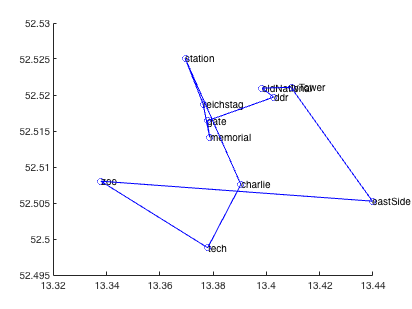

figure(2);
text([destSights(:).lat],[destSights(:).long],[destSights(:).name])
hold on;
plot([destSights(bestPath).lat destSights(bestPath(1)).lat],  [destSights(bestPath).long destSights(bestPath(1)).long], 'bo-');

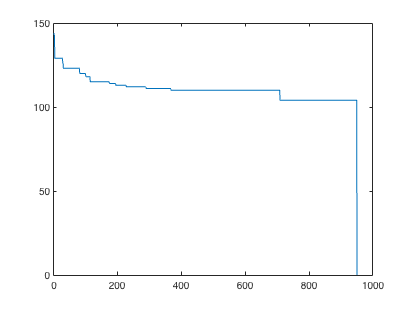



figure(3);
plot(1:maxIts, scores);